rng(7,"twister");
omap3D =  occupancyMap3D;
mapWidth = 200;
mapLength = 200;

numberOfObstacles = 10;


obstacleNumber = 1;
while obstacleNumber <= numberOfObstacles
    width = randi([1 50],1);                 % The largest integer in the sample intervals for obtaining width, length and height                                                     
    length = randi([1 50],1);                % can be changed as necessary to create different occupancy maps.
    height = randi([1 150],1);
    xPosition = randi([0 mapWidth-width],1);
    yPosition = randi([0 mapLength-length],1);
    
    [xObstacle,yObstacle,zObstacle] = meshgrid(xPosition:xPosition+width,yPosition:yPosition+length,0:height);
    xyzObstacles = [xObstacle(:) yObstacle(:) zObstacle(:)];
    
    checkIntersection = false;
    for i = 1:size(xyzObstacles,1)
        if checkOccupancy(omap3D,xyzObstacles(i,:)) == 1
            checkIntersection = true;
            break
        end
    end
    if checkIntersection
        continue
    end
    
    setOccupancy(omap3D,xyzObstacles,1)
    
    obstacleNumber = obstacleNumber + 1;
end 

% making ground as a obstacle so the UAV don't collide with it


[xGround,yGround,zGround] = meshgrid(0:mapWidth,0:mapLength,0);
xyzGround = [xGround(:) yGround(:) zGround(:)];
setOccupancy(omap3D,xyzGround,1)

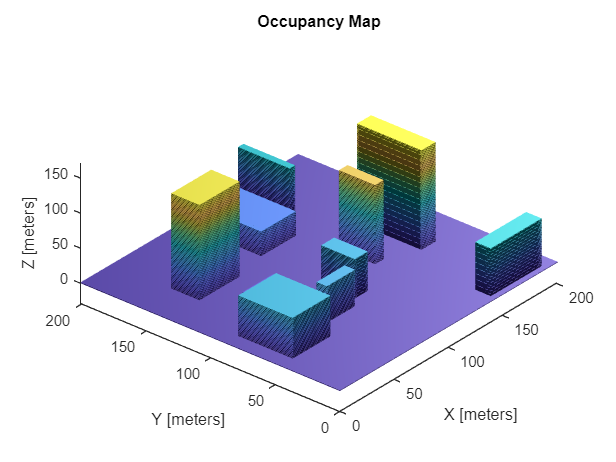

% displaying the final map
figure("Name","3D Occupancy Map")
show(omap3D)